# C&S10.1 One-Dimensional Binary Mass Transfer in a Stefan Tube Template

# Chemical Engineering Summer School Workshop Objectives

- Make a copy of this template and then modify this template to solve this problem with a Linear Temperature Profile. 

- Discuss the difficulties that you had in modifying this template.

# Objectives

- Numerically solve a second order ODE with a split boundary condition.

- Derive the mole balance for a pure liquid evaporating from a tube with a gentle flow of air at the top of the tube.

- Modify this template to solve a similar problem that includes a temperature profile in the gas phase.

- Explain to another student how the secant method is the same as 2 guesses and manual interpolations for the remaining trials

- Explain to a first year chemical engineering student how a while loop works.

- Write a simple program that contains a while loop

# 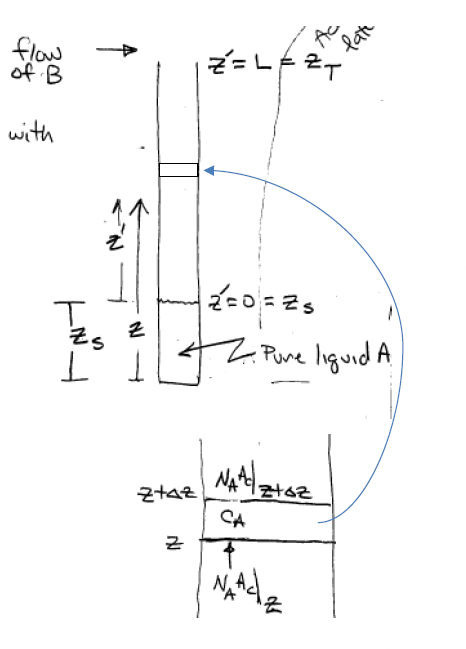

# C&S10.1 Problem Statement

Pure liquid methanol, A, is placed a the bottom of a tube and it is evaporating into a stream of gas of fluid B.  The flow of B is such that the mole fraction of A in the gas stream above the tube can be considered negligible (i.e. 0.0).  For this problem we will assume that the rate of evaporation is small and the liquid level remains essentially constant.  Determine the concentration profile of A and B in the gas space within the tube.  The values of the constants are $$C_T=\frac{P}{RT}\,$, $  \mathcal{D}=1.991\times{10}^{-5}\, $ $\frac{m^2}{s}\,$ $L=0.238\ m\,$ $P=99.4\ kPa\,$ and $p_A^{vap}=68.4\ kPa$$ at $T=328.5K$

# Procedure

- Derive differential equations for the model of your system (*e.g.* dy/dt=a-b*t)

- Create a function in MATLAB live editor that contains the differential equations (*e.g.* dy/dt=a-b*t) This must be placed at the end of the live script file (*.mlx)*

- The function name is defined using `function`` outputvariable=FUNCTIONname (t,Yfuncvec):`

- We will use `ODEfun` for the FUNCTIONname. After the function name and within parenthesis you then list the variables passed into the function: t and Yfuncvec. 

-  In the first line of code you will unpack the y vector (which in this example is `yA` and `NA`)  `yA = Yfuncvec(1)` and `NA = Yfuncvec(2)` This allows you to use the variable name `NA` and `yA` in the equations in the function

- define the two differential equations using typed variables. (*e.g.* `dyAdz = 0 - (1 - yA) * NA / (DAB * CT)` and  dNAdz = 0)

- create an array of the values of the derivatives defined above. ( *e.g.* `dYfuncvecdz = [dyAdz; dNAdz]`) Again for this case we have 2 derivatives

- End the function with the line command `end`

- Give the initial conditions (*e.g.* at z=0 what is yA and NA) as `zspan=[0,0.238]` for 0 to 0.238m

- Give the initial values of the variables. 

# Derivations

Using a control volume within the gas of $\Delta V=A_c\Delta z$ gives

Differential mole Balance in z direction


$$$$\Delta V \frac{\partial C_A}{\partial t}=N_AA_c|_z-N_AA_c|_{z+∆z}  	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(1)$$$$


Dividing by the control volume and taking the limit

	
$$$$\lim_{\Delta V \to 0} \frac{\partial C_A}{\partial t}=\frac{N_AA_c|_z-N_AA_c|_{z+\Delta z}}{\Delta V }	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(2)$$$$


Changing the numerator to always have the $$\Delta z$$ term first and then taking the limit to remove the $$\Delta 's$$ and obtain a partial derivative:

	
$$$$\frac{\partial C_A}{\partial t}=\lim_{\Delta V \to 0}\left[-\frac {N_AA_c|_{z+∆z}-N_AA_c|_z}{\pi r^2 (z+\Delta z - z)}\right]  =-\frac{\partial N_A A_c}{ \pi r^2 \partial z}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(3)$$$$


This should remind you of your calculus in which these limits are how derivatives are defined.  Since in this tube the area is a constant and it can be removed from the derivative.

	
$$$$\frac{\partial C_A}{\partial t}=-\frac{\partial\left(N_A\right)}{\partial z}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(4)$$$$


Assuming a pseudo steady-state based on the small rate of evaporation and the subsequent small changes in liquid height and concentration in the control volume.  In actual experiments with a stefan tube the rate in which the liquid height drops is less than 2 mm/hr.  The actual experiment is performed over a period of 28 hours. Assuming this pseudo steady-state gives the following equation

	
$$$$\frac{\partial\left(N_A\right)}{\partial z}=0	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(5)$$$$


Integrating this equation gives

	
$$$$N_A=constant	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(6)$$$$


The constitutive equation for mass transfer is that the flux of moles is equal to a diffusive flux and a convective flux.  For a binary system of only 2 components A and B we get:  

	
$$$$N_A=J_A+y_A\left(N_A+N_B\right)	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(7)$$$$


We can perform a mole balance on component B to arrive at 

	
$$$$\frac{\partial C_B}{\partial t}=-\frac{\partial\left(N_B\right)}{\partial z}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(8)$$$$


And 

	
$$$$\frac{\partial\left(N_B\right)}{\partial z}=0	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(9)$$$$


Integrating this equation gives

	
$$$$N_B=\text{constant}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(10)$$$$


If we assume that B is not soluble in liquid A then the flux of B into the liquid surface is zero.  Since the flux of B is a constant then this constant must be zero $N_B=\text{constant}=0$ This is known as unimolecular diffusion (UMD)  Placing this result into equation 7 results in

	
$$$$N_A=J_A+y_A\left(N_A+0\right)	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(11)$$$$


And solving for the flux of A

	
$$$$N_A=\frac{J_A}{1-y_A}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(12)$$$$


The diffusive flux of A has been found to be from experiments

	
$$$$J_A=-C_T\mathcal{D}\frac{dy_A}{dz}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(13)$$$$


The two ODE's that we will solve are 

	
$$$$\frac{dy_A}{dz}=-\frac{N_A\left(1-y_A\right)}{C_T\mathcal{D}}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(14)$$$$\frac{\partial N_A}{\partial z}=0	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(15)$$
	
$$


Equations (14) and (15) could be combined into a second order differential equation for $$y_A$$ with respect to z, but for a numerical solution you need ODE's. 

We will need a boundary condition for each ODE.  But we only know one boundary condition at the first surface (mole fraction at z=0) and the second boundary condition at the second surface (Concentration of A is 0 at z=L).  

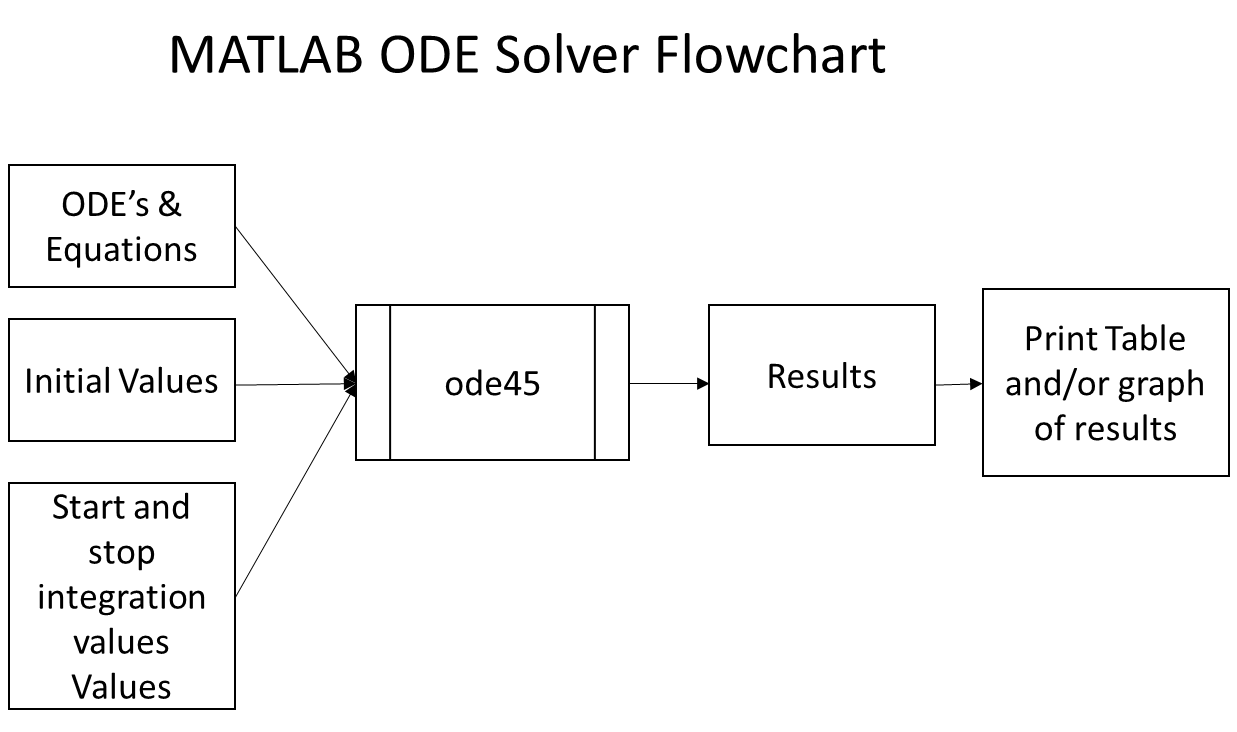

## Clear the output in the "command window" using clc;

clear, clc, format short g, format compact

Below is the text required in the function the contains the differential equations $$$\frac{dy_A}{dz}=-\frac{N_A\left(1-y_A\right)}{C_T\mathcal{D}}	$$$$\frac{\partial N_A}{\partial z}=0$$
	$  This is the main part that the user needs to modify to solve a system of ODE's.  This actual function is located at the end of this file.  Function containing the ODE's

## Overall flow chart for solving this system of ODE's.  3 inputs of the ODEfun, y0 and zspan.

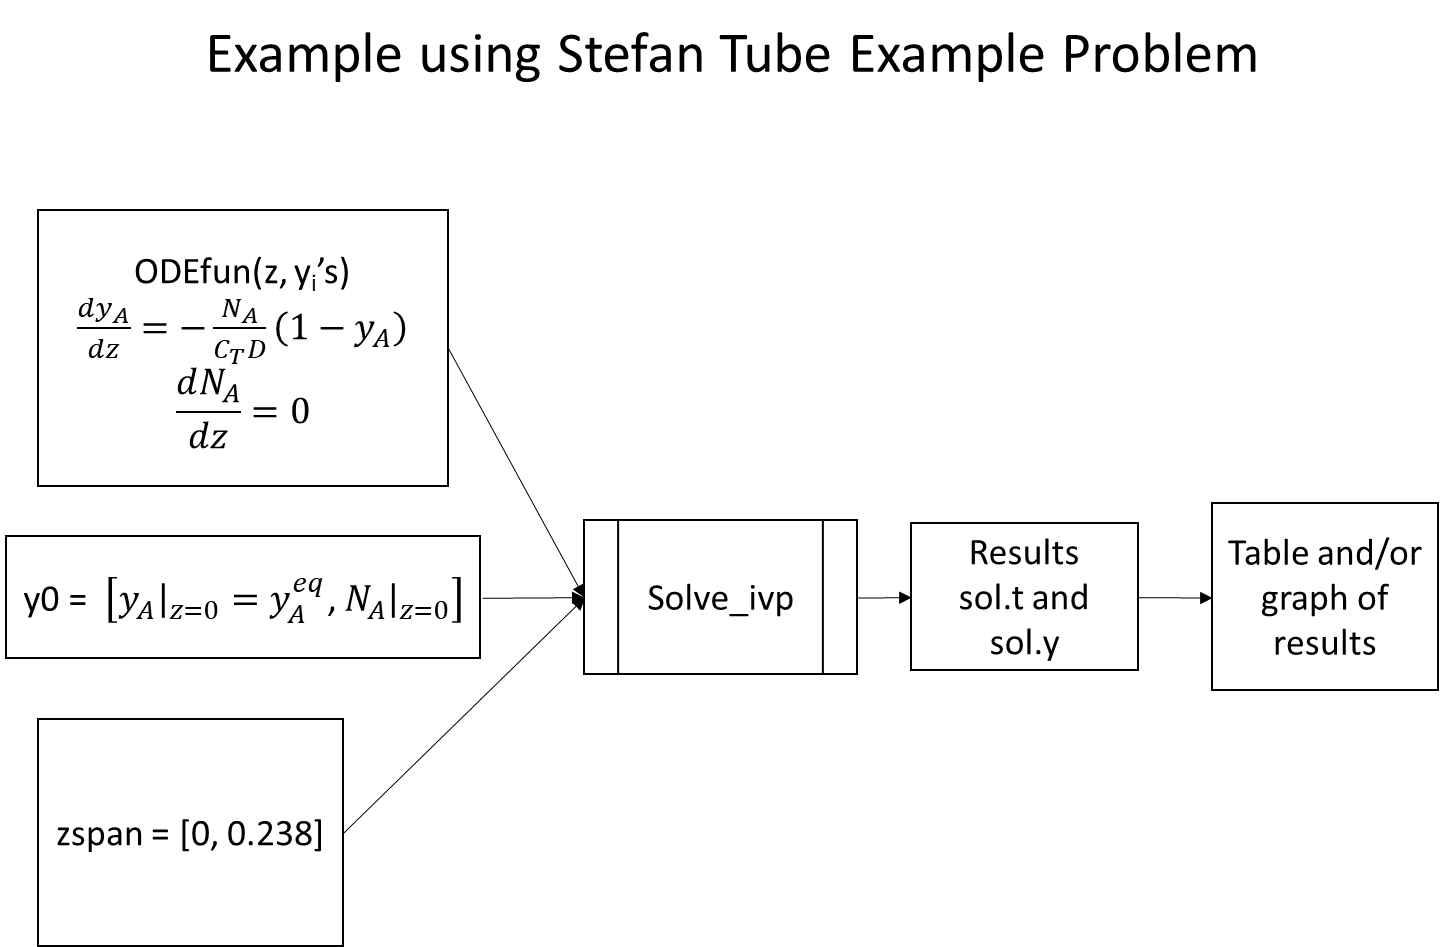

## Split Boundary Value Explanation

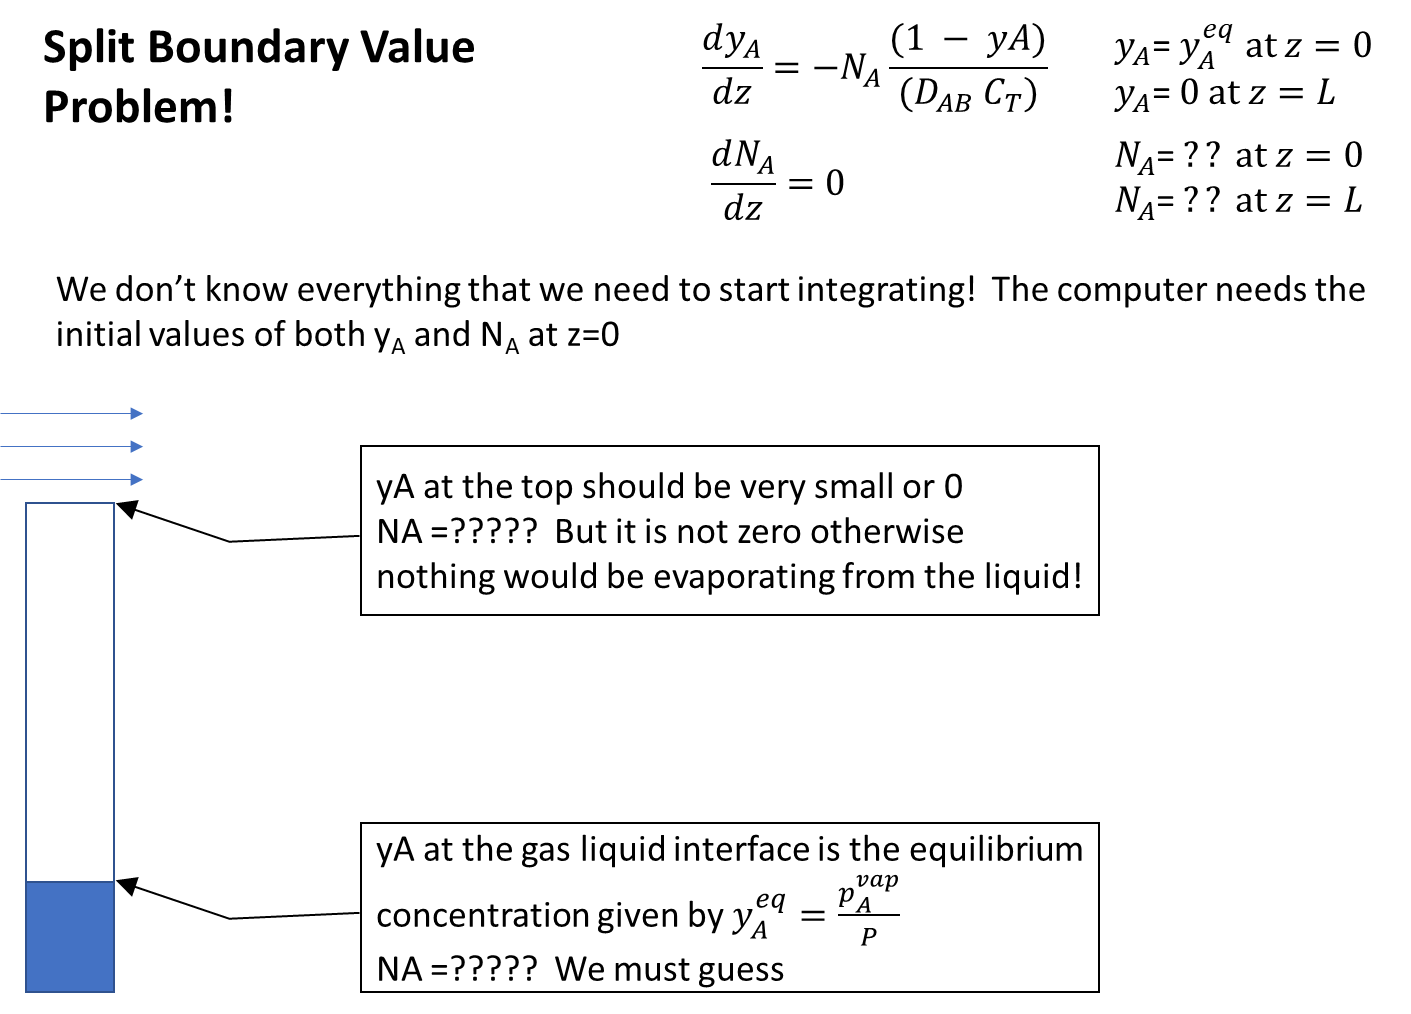

Our ODE solver calculates final conditions when given initial conditions, so how do we deal with knowing the final condition (z=L), but not the initial condition (z=0)?

We'll use a technique called the shooting method.  With the shooting method we guess an initial value, run the solver, compare the final value to our target value. If they are equal we are done!  

Then we make a second guess, and then repeat until we find a solution.  So we keep shooting, correcting our aim each time, 

until we hit the target.

How to make a good guess? That depends on the problem, but a good strategy is to make one guess that's the right order of magnitude, make a second that is significantly more or less than the first guess (half, twice?), then interpolate for your third (and continuing) guess after that based on your first two results.  

Making a good first guess shouldn't matter as long as you're somewhere in the general vicinity of the answer.

One of the boundary conditions for these equations is at the surface of the liquid in which we assume that the gas and liquid are in equilibrium.  This phase equilibrium can be written as 

	
$$$$y_AP\phi_A=x_A\gamma_Ap_A^{vap}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(16)$$$$


In the above equation we will assume that the correction factors of $$\phi_A$$ and $$\gamma_A$$ are assumed to be ideal solutions and equal to 1.  Since the liquid is pure A then $x_A=1$ Letting the liquid surface be at z=0 the boundary conditions are:

	
$$$$\left.N_A\right|_{z=0}=constant	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(17)$$
	$$\left.y_A\right|_{z=0}=\frac{p_A^{vap}}{P}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(18)$$$$


At the top of the tube we have already stated that the concentration of A is negligible 

	
$$$$\left.y_A\right|_{z=L}=0	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(19)$$
	$$\left.N_A\right|_{z=L}=constant	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(20)$$$$


The values of the constants are $$C_T=\frac{P}{RT}\,$, $  \mathcal{D}=1.991\times{10}^{-5}\, $ $\frac{m^2}{s}\,$ $L=0.238\ m\,$ $P=99.4\ kPa\,$ and $p_A^{vap}=68.4\ kPa$$

## Analytical Solution

The analytical solution for a constant temperature in the gas phase of the tube is

	
$$$$N_A=-\frac{C_T\mathcal{D}}{L}ln\left(1-\left.y_A\right|_{z=0}\right)	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(21)$$$$


And the concentration profile is given as 

	
$$$$\left(\frac{1-y_A}{\left(1-\left.y_A\right|_{z=0}\right)}\right)=\left(\frac{1}{\left(1-\left.y_A\right|_{z=0}\right)}\right)^{z/L}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(22)$$$$


## Estimation of the initial values of NA and yA

The initial guesses for the flux of A ($$N_A$$) can be obtained from by assuming a constant temperature and using $$\frac{y_A^{eq}}{2}$$ as our estimate for $$y_A$$ and estimating $dy_A/dz$ as 


$$$$\frac{dy_A}{dz}=\frac{({y_A}^{eq} - 0)}{\text{tube length} = 0.238m}$$$$


*i.e.*

	
$$$$N_A=\frac{J_A}{1-y_A}=\frac{-C_T\mathcal{D}\frac{dy_A}{dz}}{1-y_A}=\frac{-\left(\frac{P}{RT}\right)\mathcal{D}\frac{dy_A}{dz}}{\left(1-y_A\right)}\approx\frac{99.4\times 10^{3}}{8.314*298.15}\frac{2\times 10^{-5}*\frac{0.688}{0.238}}{(1-0.688/2)}=0.00353 \frac{mol}{m^2 \,s}	\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(23)$$$$


%estimating a starting value of NA
NAest=99.4e3/8.314/298.15*2e-5*.688/0.238/(1-0.688/2)

NAest =     0.0035341

yAeq=68.4/99.4

yAeq =       0.68813

"hand calculations"

%estimating a starting value of NA
NAest=99.4e3/8.314/298.15*2e-5*.688/0.238/(1-0.688/2)

NAest =     0.0035341

yAeq=68.4/99.4

yAeq =       0.68813



y0 = [yAeq NAest];  % Initial values for the dependent variables
zspan = [0 0.238]; % Range for the independent variable

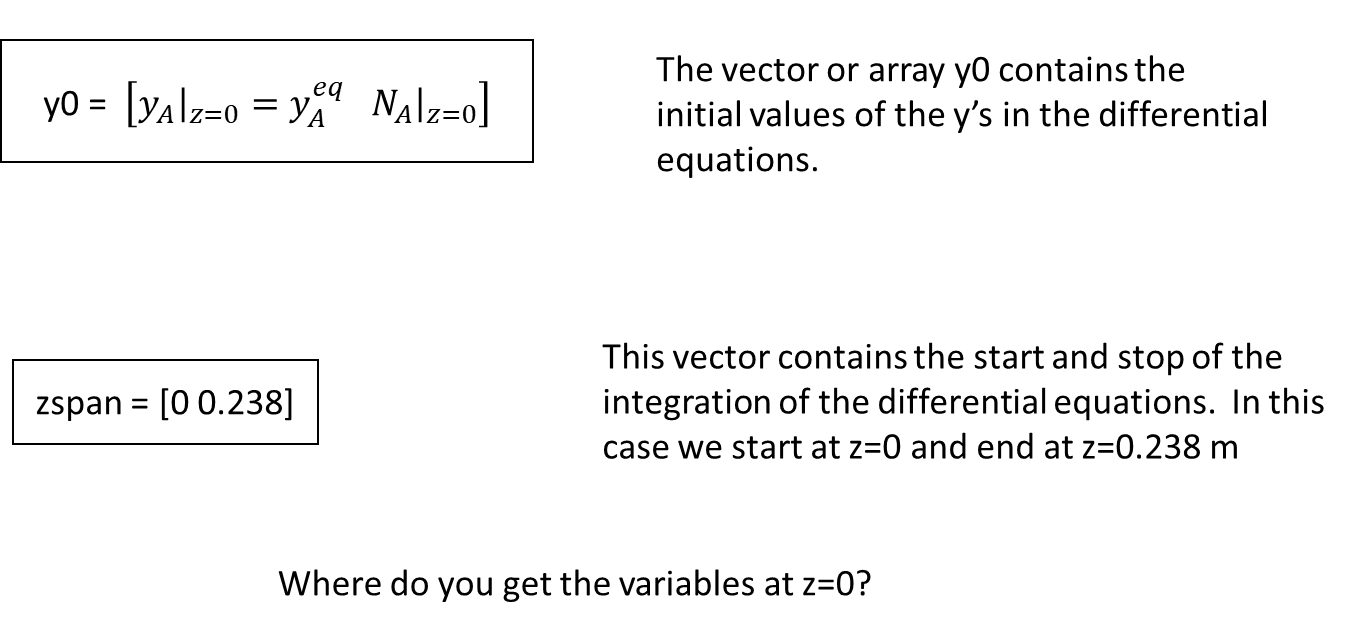

## 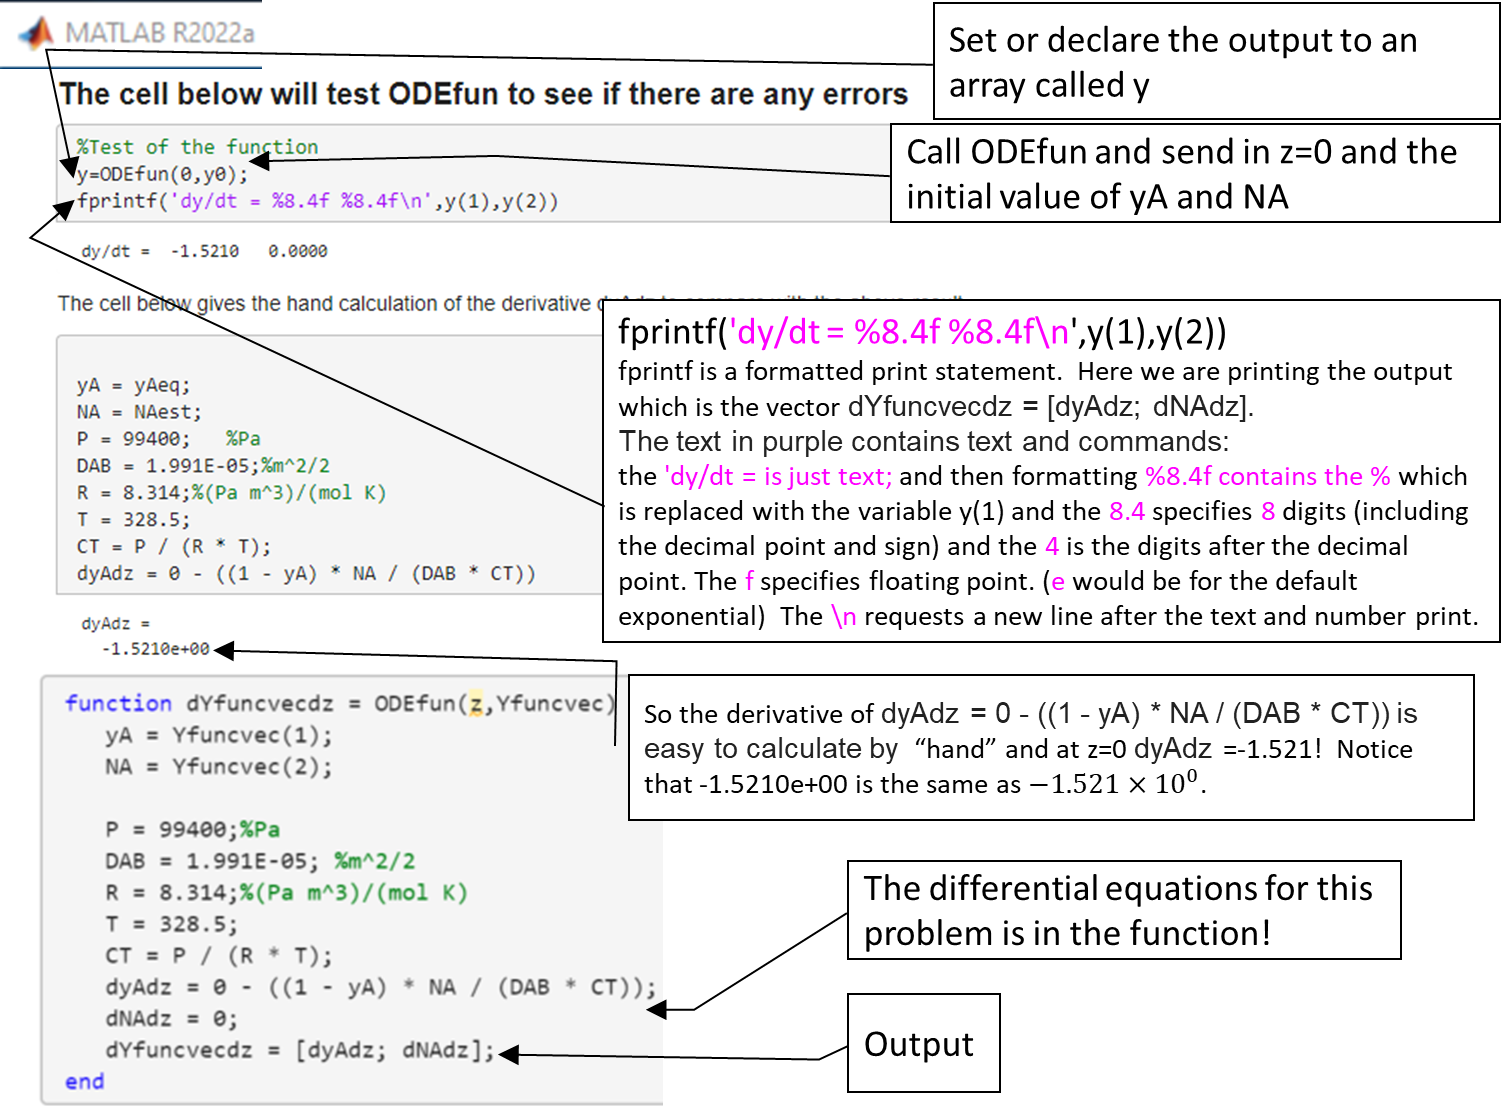

## The cell below will test ODEfun to see if there are any errors

%Test of the function
y=ODEfun(0,y0);
fprintf('dy/dt = %8.4f %8.4f\n',y(1),y(2))

dy/dt =  -1.5210   0.0000


The cell below gives the hand calculation of the derivative dyAdz to compare with the above result


yA = yAeq;
NA = NAest;
P = 99400;   %Pa
DAB = 1.991E-05;%m^2/2
R = 8.314;%(Pa m^3)/(mol K)
T = 328.5;
CT = P / (R * T);
dyAdz = 0 - ((1 - yA) * NA / (DAB * CT))

dyAdz =        -1.521

## Next we will solve the ODE's

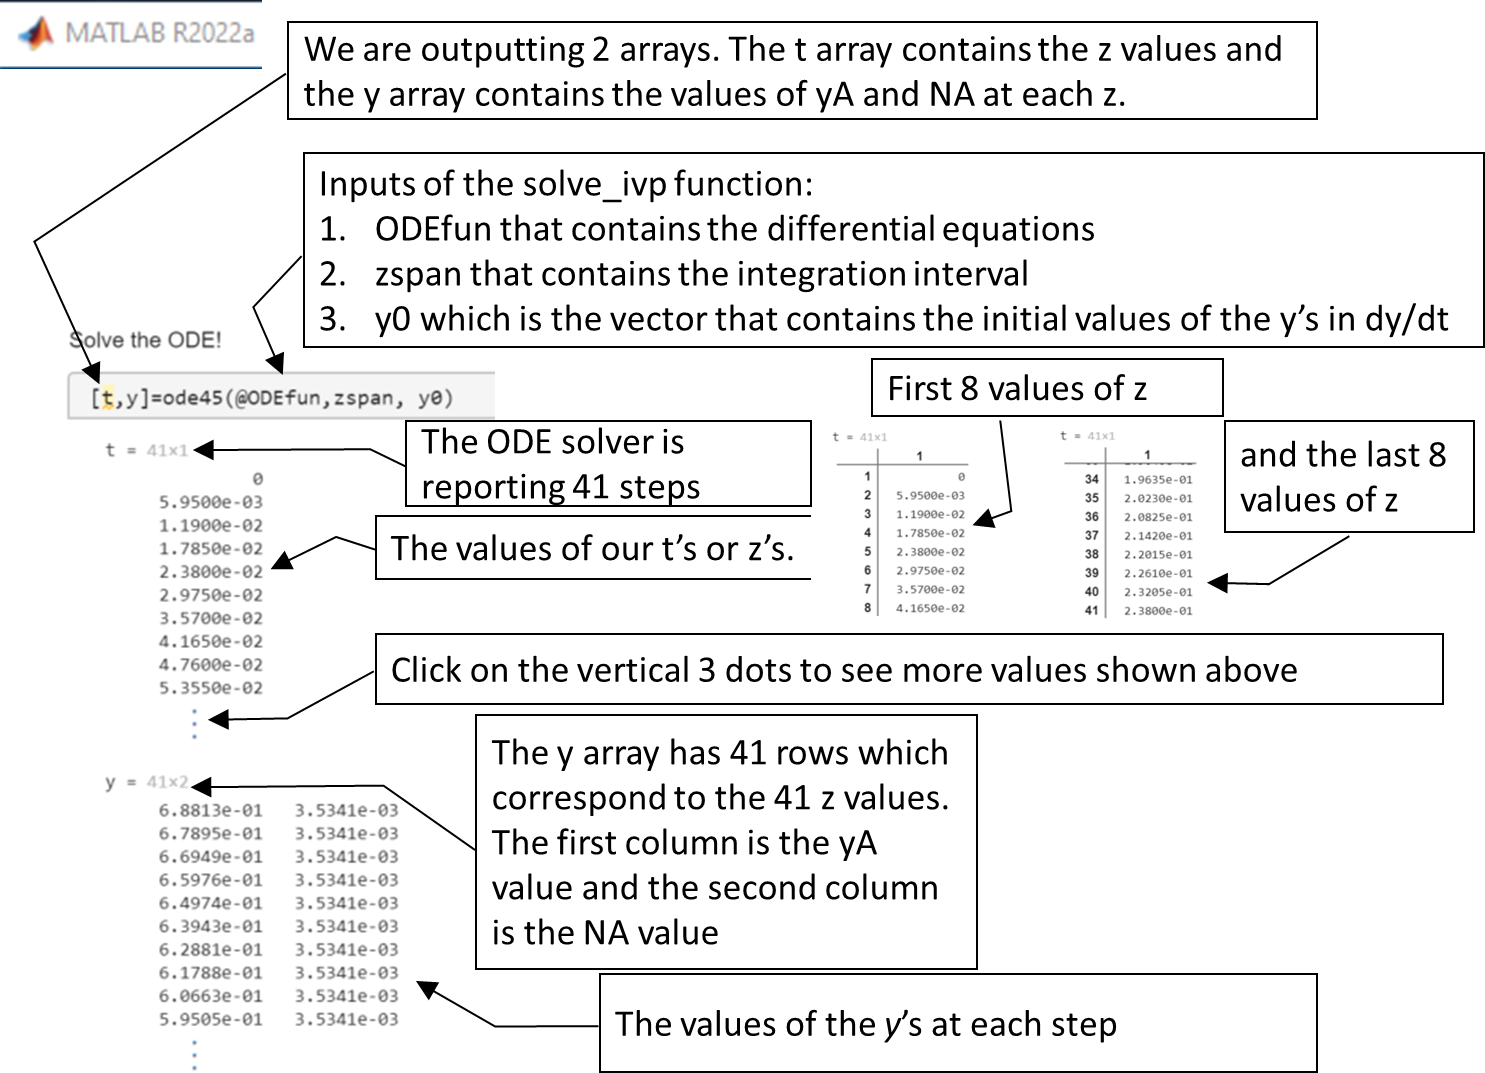

Solve the ODE!

[t,y]=ode45(@ODEfun,zspan, y0)

t =             0
      0.00595
       0.0119
      0.01785
       0.0238
      0.02975
       0.0357
      0.04165
       0.0476
      0.05355


y =       0.68813    0.0035341
      0.67895    0.0035341
      0.66949    0.0035341
      0.65976    0.0035341
      0.64974    0.0035341
      0.63943    0.0035341
      0.62881    0.0035341
      0.61788    0.0035341
      0.60663    0.0035341
      0.59505    0.0035341


We can either expand the above or look at the last row to see if yA=0 at the top.  Almost!

length(y)

ans =     41

fprintf('yA|top = %8.6e \n',y(length(y),1));

yA|top = 4.391329e-03 


fprintf('NA = %8.6e \n',y(length(y),2));

NA = 3.534103e-03 


The results shown in the 2 solution arrays above show the t and y variables.  (Remember the ode45 assumes that the independent variable is called t, but we are using z!) You can see that t (z for us) goes from 0 to 0.238 m. From the liquid interface to the top of our tube.

The y array has the values of 𝑦𝐴 (first column) and 𝑁𝐴 (second column).

𝑁𝐴 doesn't change, because we made it's derivative 0. 𝑦𝐴 decreases from its initial value of 0.688 down to   0.0043913. That's not far enough! We need the yA value at the top to be 0, but that's OK. We're close.

We need a second guess for our flux at z=0, and then we'll interpolate to find a value that gets 𝑦𝐴 to 0 at the top of the tube (z = 0.238 m). Because our first guess for flux is too low (the mole fraction at the top was not zero) let's use 1.2 times the NAest as our second guess. Note that if we used one half of NAest instead, we could still proceed and find our solution. The guesses just need to be somewhere in the approximate ballpark. Below is our second NA|z=0 guess.

%Second Guess:
NAest2= NAest*1.2  %Replace this with your new guess and run (ctrl enter) 

NAest2 =     0.0042409

y0 = [yAeq, NAest2] % Initial values for the 2 dependent variables 

y0 =       0.68813    0.0042409


fprintf('NAest2=',NAest2)

NAest2=

[t,y]=ode45(@ODEfun,zspan, y0)

t =             0
      0.00595
       0.0119
      0.01785
       0.0238
      0.02975
       0.0357
      0.04165
       0.0476
      0.05355


y =       0.68813    0.0042409
      0.67708    0.0042409
      0.66563    0.0042409
      0.65379    0.0042409
      0.64152    0.0042409
      0.62881    0.0042409
      0.61566    0.0042409
      0.60204    0.0042409
      0.58794    0.0042409
      0.57334    0.0042409


Now we have a negative value for yA at the top!

fprintf('yA|top = %16.6e \n',y(length(y),1));

yA|top =    -2.557736e-01 


# Guessing Games

Based on these 2 guesses we see that the NAest=0.003534 gives a small yA value (4.2409e-3) but it is not less than 1e-6.  Close but not zero!

So you could manually keep guessing to get a $yA|_{\text{top}}$ value less than 1E-6. Try it in the cell below. How many guesses did it take?

Copy this line below with a number for the new guess: `y0 = [yAeq, new Guess]`  then call the ODE solver using this line:   `[t,y]=ode45(@ODEfun,zspan, y0)  `Finally examine the last yA value using the fprintf command:` fprintf('yA|top = %16.6e \n',y(length(y),1));`

%Trial 3
%Copy this line below y0 = [yAeq, new Guess]  then call the ODE solver
%[t,y]=ode45(@ODEfun,zspan, y0) then print last value  fprintf('yA|top = %16.6e \n',y(length(y),1));




%Trial 4
%Copy this line below y0 = [yAeq, new Guess]  then call the ODE solver
%[t,y]=ode45(@ODEfun,zspan, y0)    then print last value  fprintf('yA|top = %16.6e \n',y(length(y),1));





%Trial 5
%Copy this line below y0 = [yAeq, new Guess]  then call the ODE solver
%[t,y]=ode45(@ODEfun,zspan, y0) then print last value   fprintf('yA|top = %16.6e \n',y(length(y),1));






How many guesses did that take?  Too many to get to 1E-6

# Interpolation: Smart guessing or systematic root finding!

Interpolate between these two values to try to get yA=0 on your next guess. So your 2 pairs of points are in the format of (NA|z=0,yA|z=top)

disp('These are the 2 pairs of points')

These are the 2 pairs of points


fprintf('%8.6f %8.6f',NAest,0.00424092);

0.003534 0.004241

fprintf('%8.6f %8.6f',NAest2,y(length(y),2));

0.004241 0.004241

disp('interpolate to find the next value of NA|z=0 given by the intersection of the dashed line and blue line');

interpolate to find the next value of NA|z=0 given by the intersection of the dashed line and blue line


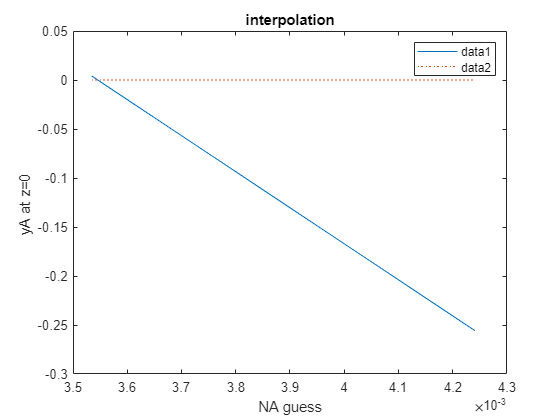

plot([NAest NAest2],[0.00424092 y(length(y),1)],'-',[NAest, NAest2],[0.000, 0],':')
xlabel('NA guess');
ylabel('yA at z=0 ');
legend();
title('interpolation');

As you can see by the above graph our first estimate nearly gave us the answer of zero.  Next you will interpolate to find the next value of NA|z=0 given by the intersection of the dashed line and blue lineInterpolation.  This is done using the following interpolation formula: 


$$$$\frac{(y_1 - y_2)}{(x_1-x_2)}=\frac{(y_1 - 0)}{(x_1-x)}$$$$


Solving for x gives


$$$$x=x_1-y_1\frac{(x_1-x_2)}{(y_1 - y_2)}$$$$


So your next guess should be


$$$$x=0.003534-0.00424\frac{(0.003534-0.0042409)}{(0.00424092 - (-0.2557973852641636))}$$$$


x=0.003534-0.00424*(0.003534-0.0042409)/(0.00424092 - (-0.2557973852641636))

x =     0.0035455


fprintf('%8.6f ',x);

0.003546 

Use this cell for your 3rd trial

4th Trial

5th Trial

We could always do these series of interpolations by hand, but wouldn't it be better to automate this process? The mathematical technique that we were using with interpolations is called the secant method.  It looks at the results of the last two guesses, and makes a new estimate based on how close the previous guesses were to the target.  If the problem was linear, it would find the correct solution on the third guess.  For a non-linear problem, it will still get to the solution, but it will take a few iterations to find it.  Remember that we're guessing our initial flux NA, and our target is to get yA to be 0 after integrating z from 0 to 0.238 meters.

To find the correct value for N_A, we will start using the same 2 initial guesses of the value of $N_A |_{z=0}$.  The result for each $N_A$ guess will be calculated after integrating. At $z=0.238$ we want the value of $y_A|_{z=0.238}$ to be zero. The difference between our result and 0 is the error for that guess.


$$$$err(N_A)= y_A|_{z=0.238} -0$$ $$


Of course the desired result is to have zero error which in computer language is an error value less than 1e-6 $$(1\times 10^{-6})$$

After the first two guesses, we can make a good third trial (and after that a fourth one, and so on) by using the secant method or linear interpolation.  

In this case the pairs of points are the two guesses for $$N_A$$ and the two resulting values for $$y_A|_{z=0.238}$$. 


$$$$N_{A_{k+1}}=N_{A_k}-err_k\frac{ N_{A_k}-N_{A_{k-1}} } {err_k-err_{k-1}}$$$$


Two initial values or guesses of $N_A$ are needed.

# 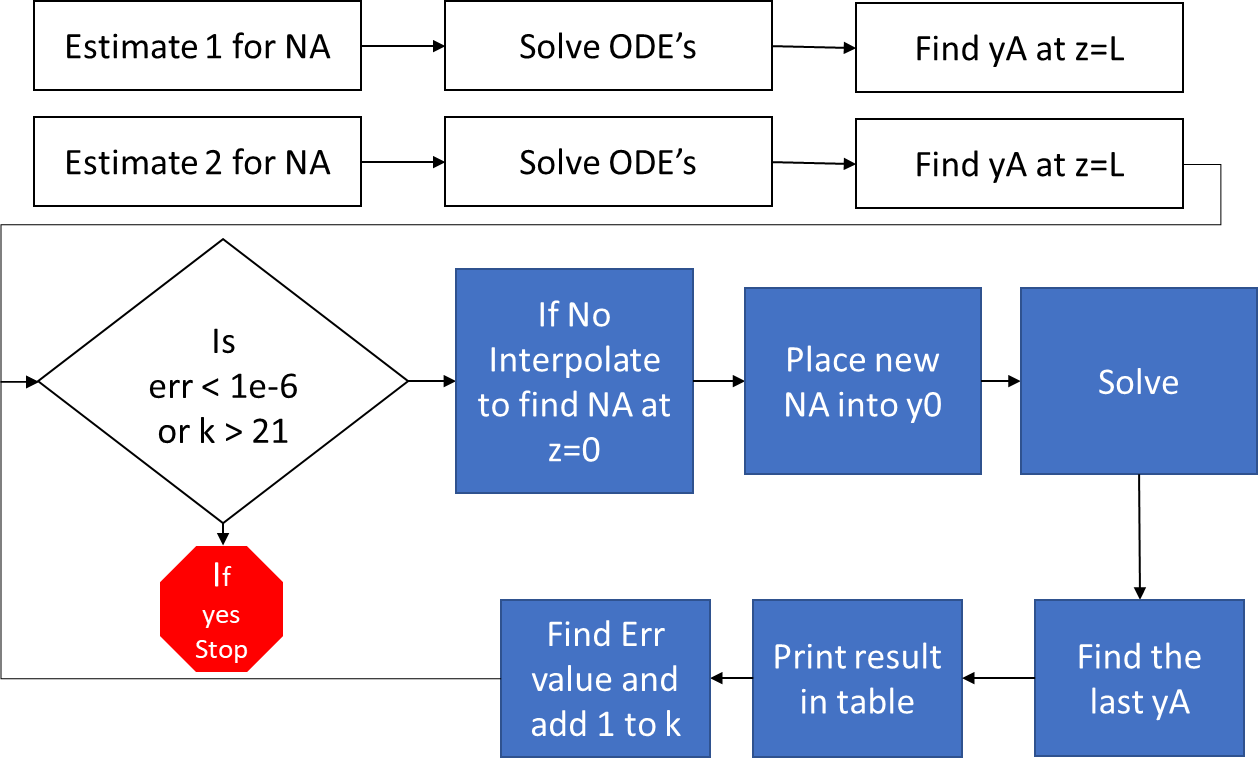

%initialize arrays
yini(22)=0;
f(22)=0;
%input first 2 guesses
yini(1)=NAest;
yini(2)=NAest2;


k=1; %MATLAB starts arrays at 1
y0=[yAeq,yini(1)]; %y0 = [yAeq, new Guess] Initial values for the dependent variables
[t,y]=ode45(@ODEfun,zspan,y0); %solve the ODE with first guess
f(k)=y(end,1);
k=2;
y0=[yAeq,yini(2)];
[t,y]=ode45(@ODEfun,zspan,y0); %solve the ODE with second guess
f(k)=y(end,1);
err=abs(f(k));

while (err>1e-6) && (k<20) %multiple iterations to get err<1e-6
    if k==2%This prints a table in the space below
        fprintf('\t%s\n','Summary of iterations');
        fprintf('%s\t\t%s\t\t%s\n','Trial','NA|z=0','yA|top');
        fprintf('%2.0f\t     %10.8f\t  %13.4e\t \n',1,yini(1),f(1));
        fprintf('%2.0f\t     %10.8f\t  %13.4e\t \n',2,yini(2),f(2));
    end
    yini(k+1)=yini(k)-f(k)*(yini(k)-yini(k-1))/(f(k)-f(k-1));
    y0=[yAeq,yini(k+1)];
    [t,y]=ode45(@ODEfun,zspan,y0);
    f(k+1)=y(end,1);
    err=abs(f(k+1));
    k=k+1;
    fprintf('%2.0f\t     %10.8f\t  %13.4e\t \n',k,yini(k),f(k));
end

	Summary of iterations


Trial		NA|z=0		yA|top


 1	     0.00353410	     4.3913e-03	 


 2	     0.00424092	    -2.5577e-01	 


 3	     0.00354603	     4.8237e-04	 
 4	     0.00354734	     5.2862e-05	 
 5	     0.00354750	    -1.2754e-08	 


# Print a table of the ODE output

numrows=11;
teval = linspace( zspan(1),zspan(2) , numrows );
[t,y]=ode45(@ODEfun,teval, y0);

P = 99400; %Pa
DAB = 0.00001991; %m^2/2
R = 8.314; %(Pa m^3)/(mol K) 
T = 328.5;   
CT = P / (R * T); 
yA1 = 68400 / P;
L = 0.238 ;
NA_anal = DAB * CT * log((1 - 0) / (1 - yA1)) / L; %This is the theoretical result from the text

for i=1:numrows
    if i==1
        fprintf('%s %13.6e\t %s %13.6e\t ','NA (mol/m^2/s) =', y(end,2),'NA_anal(mol/m^2/s)=',NA_anal)
        fprintf('%s\t\t %s\t %s\n','     z',        '    yA',       '           yA_ANAL');
        fprintf('%s\t\t %s\t %s\n','    (m)',        '(mol frac)',       '(mol frac)');
    end
    y_anal(i)=1 - ((1 - yA1) * (1 / (1 - yA1))^((t(i) - 0) / (L - 0)));  %Theoretical value for y to compare
    fprintf('%8.4f\t %8.4f\t  %8.4f\n', t(i),y(i,1),y_anal(i));              %\t is a tab, \n new line, 
end

NA (mol/m^2/s) =  3.547502e-03	 NA_anal(mol/m^2/s)=  3.547502e-03	 

     z		     yA	            yA_ANAL


    (m)		 (mol frac)	 (mol frac)


  0.0000	   0.6881	    0.6881
  0.0238	   0.6496	    0.6496
  0.0476	   0.6063	    0.6063
  0.0714	   0.5576	    0.5576
  0.0952	   0.5030	    0.5030
  0.1190	   0.4415	    0.4415
  0.1428	   0.3725	    0.3725
  0.1666	   0.2950	    0.2950
  0.1904	   0.2079	    0.2079
  0.2142	   0.1100	    0.1100
  0.2380	  -0.0000	    0.0000


Make a plot of the output

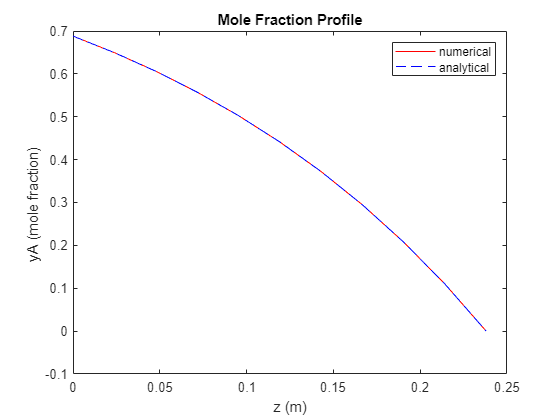

plot (t,y(:,1),'-r','DisplayName','numerical');
hold on
plot (t,y_anal,'--b','DisplayName','analytical');
hold off
xlabel('z (m)');
ylabel('yA (mole fraction) ');
legend();
title('Mole Fraction Profile');

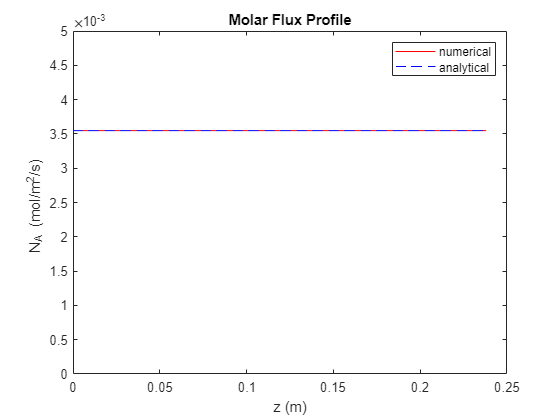

plot (t,y(:,2),'-r','DisplayName','numerical');
hold on
plot ([t(1) t(end)],[NA_anal NA_anal],'--b','DisplayName','analytical');
hold off

xlabel('z (m)');
ylabel('N_A (mol/m^2/s) ');
legend();
title('Molar Flux Profile');
ylim([0, 0.005]);

# Use the template to solve a real problem where we don't have an analytical solution!

A further complication in the problem will be to assume that there is a linear temperature profile in the gas phase in which the gas next to the liquid is 328.5K and at the top of the tube is 295K.  You can assume that the diffusion coefficient is a function of temperature given by

  
$$$$\left.\mathcal{D}\right|_T= \mathcal{D}|_{25\degree C}\left(\frac{T}{298.15K}\right)^{1.75}  \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;(24)$$$$


Modify the ODEfun to solve for the new $y_A$ profile and make plots of $N_A$ and $y_A$ as a function of $z$`.  `

## Reflections: Comment on the difference that the temperature profile makes on the following

- Evaporation rate of liquid. (Be quantitative; give a percent difference)

- mole fraction profile. The best way to comment on this is to make a graph plotting both profiles. 

# Function containing the ODE's

function dYfuncvecdz = ODEfun(z,Yfuncvec)
   yA = Yfuncvec(1);
   NA = Yfuncvec(2);
   
   P = 99400;%Pa
   DAB = 1.991E-05; %m^2/2
   R = 8.314;%(Pa m^3)/(mol K)
   T = 328.5;
   CT = P / (R * T);
   dyAdz = 0 - ((1 - yA) * NA / (DAB * CT));
   dNAdz = 0;
   dYfuncvecdz = [dyAdz; dNAdz];
end